# %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

# %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

# % Authors: Khanh Dao Duc, Jalal Khouhak

# %         Department of Mathematics 

# %         The University of British Columbia (UBC)

# % 2022

# %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

# %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

# Script for Fitting Experimental Data %%%%%%%%%%%%%%%%%%%%%%%%%%%%%

format shortG

%%%%%%%%% Experimental Data %%%%%%%%%
% Parameter selection input
param_selection = [true; %\ alpha_P - production rate of protein
    false; % alpha_M - production cost of mRNA
    true; % alpha_E - production cost of resources
    true; % delta_P - degradation rate of protein
    false; % delta_M0 - degradation rate of mRNA
    false; % delta_E - degradation rate of resources
    true; % Betta- recycle of protein into resource
    true; % delta_M1 - recycle of mRNA into resource
    ];
scale_limits = [4 4; 
    -3 -2;
    -3 -2;
    -6 -5;
    -6 -3;
    -6 -3;
    -12 -10;
    -4 -3]; % scale limits for the active parameters in order of appearance/ to initiate the values, we first look at the best order of magnitude to work on with each parameters

% Data input - input your data here
time_points = [15,30,45,60,90,120,150];
file_name = "P.Falciparum CFPSS";

% No pre-incubation data

data_points_no_inc = [18.58333333,37.30566667,19.54631113,19.11111667,18.66668333,22.55558333;
    6092.51,11866.83333,24289.32777,25277.35,58329.06667,143137.3333;
    31081.61667,80876.33333,155640.111,199506.8333,393907.5,730762.3333;
    47467.83333,142514.1667,281197.889,424508.8333,887579.8333,1605118.333;
    58311.1,193246.5,402180.1113,709548.6667,1643731.667,3275698.333;
    61394.15,194404.5,429591.5557,780483,2058018.333,4467783.333;
    57774.4,192915,415283.122,789057.5,1986131.667,4640705]; %P.F

% Pre-incubation data
data_points_inc = [23.0278,20.94446667,20.0278,20.8889;
    17815.31667,24768.45,11197.47667,30144.08333;
    61178.38333,165426.3333,45311.63333,185069;
    88255.15,307826.6667,69455.95,312446.8333;
    98001.66667,455530.5,81043.03333,436292.1667;
    102727.8333,479963.6667,82493.28333,467082.6667;
    92647.28333,467688.2,74704.38333,449602.3333]; %P.F

protein_level_no_inc = transpose(data_points_no_inc(:,[1 2 3 4]));
concentrations_no_inc = [10 25 50 100];

protein_level_inc = transpose(data_points_inc);
concentrations_inc = [10 50 10 50];
preincubation_times_inc = [15 15 30 30];

choose_inc = [];
protein_level_inc = protein_level_inc(choose_inc,:);
concentrations_inc = concentrations_inc(choose_inc);
preincubation_times_inc = preincubation_times_inc(choose_inc);

loss_scale = time_points .^-0.3;
loss_scale = length(loss_scale)*loss_scale/sum(loss_scale);

%%%%%%%%% Auxiliary setup %%%%%%%%% 
% These routines are setup for model fitting - don't change unless necessary
% General Input
n = sum(param_selection); % number of active parameters
preincubation_times_no_inc = zeros(1, length(concentrations_no_inc));
protein_level = [protein_level_no_inc; protein_level_inc];
concentrations = [concentrations_no_inc concentrations_inc];
preincubation_times = [preincubation_times_no_inc preincubation_times_inc];
param_selection = transpose(param_selection);

% Nelder-Mead Parameters
Nb_step = 2000;
neld_param = [1 0.5 2 0.5];

% Simulation Parameters (Runge Kutta)
TIME = ceil(max(time_points)/10)*10;  % Time of simulation (in min)
deltat = 0.1; % Numerical time step (min)

Starting IVT model fit with following parameters turned on:
    "a_P"    "a_R"    "d_P"    "betta"    "gamma"

Scale found:
        10000         0.01        0.001        1e-06        0.001

Starting Nelder-Mead method with 2000 steps. 
Progress: 10% (step 200) 
       2291.2   0.00032234     0.019677    8.675e-06     0.013961

Progress: 20% (step 400) 
       1409.9   0.00017964     0.022197   1.4078e-05     0.010215

Progress: 30% (step 600) 
       1406.3   0.00018142     0.022164   1.4099e-05     0.010158

Progress: 40% (step 800) 
       937.22   0.00013038      0.01573   2.1192e-05     0.014017

Progress: 50% (step 1000) 
       683.14   9.8166e-05     0.015497   2.8507e-05     0.011378

Progress: 60% (step 1200) 
       459.27   6.2035e-05      0.01338   4.2803e-05     0.010309

Progress: 70% (step 1400) 
       458.55   6.1815e-05      0.01339   4.2876e-05      0.01029

Progress: 80% (step 1600) 
       458.55   6.1815e-05      0.01339   4.2876e-05      0.01029

Progress: 90% (

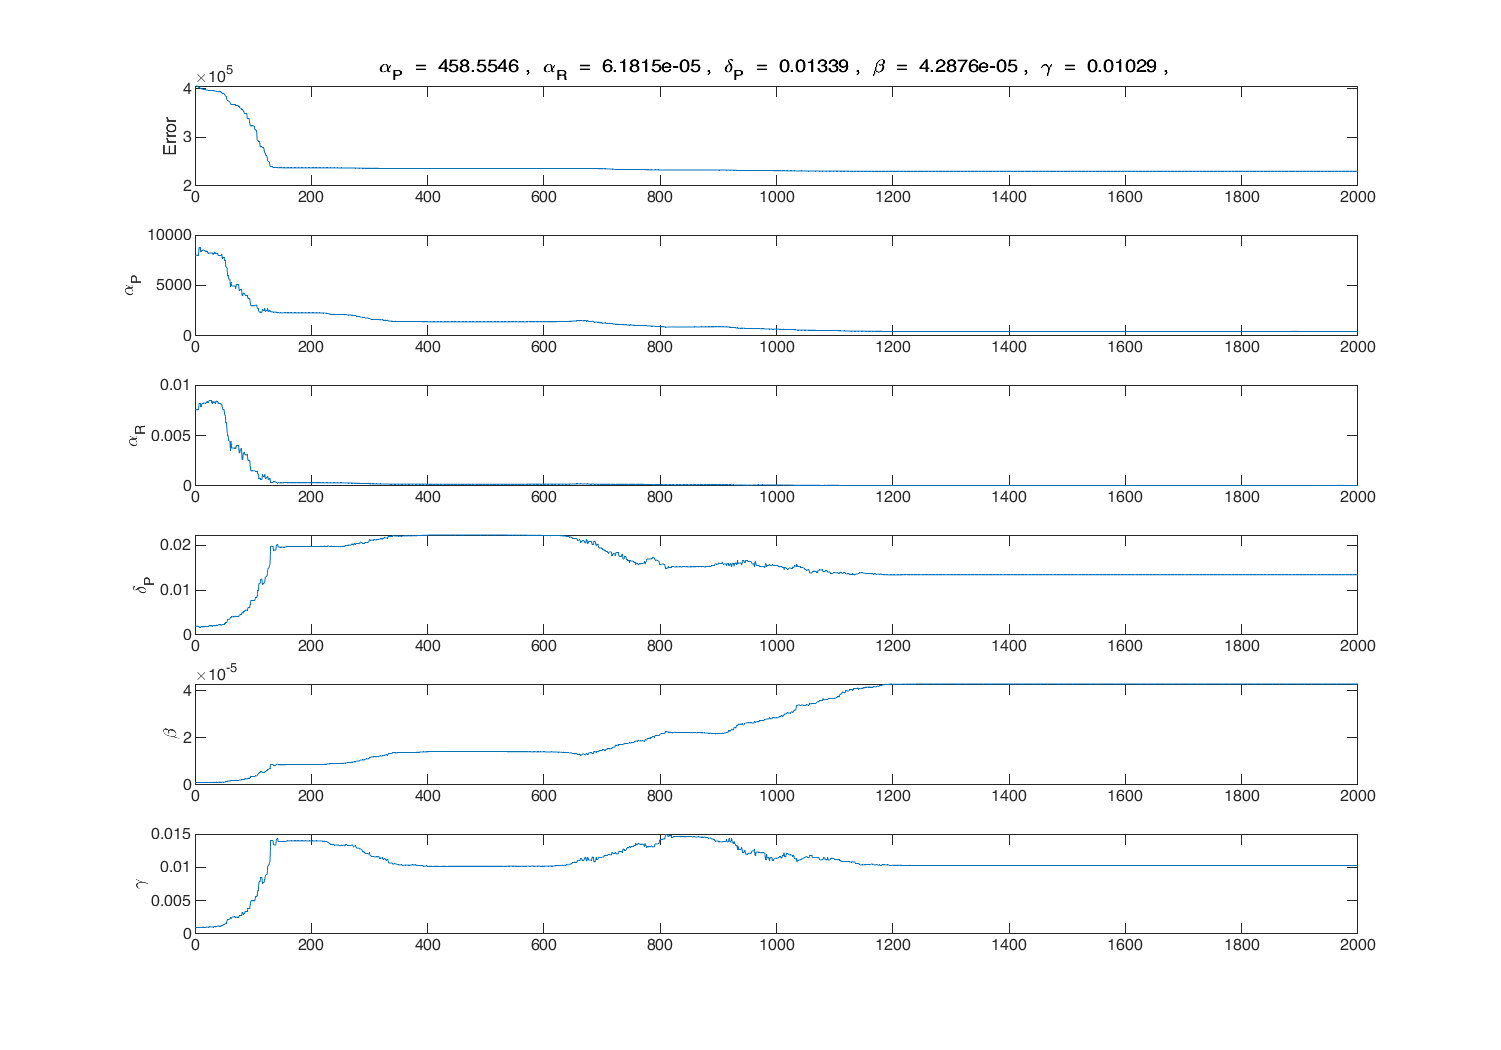

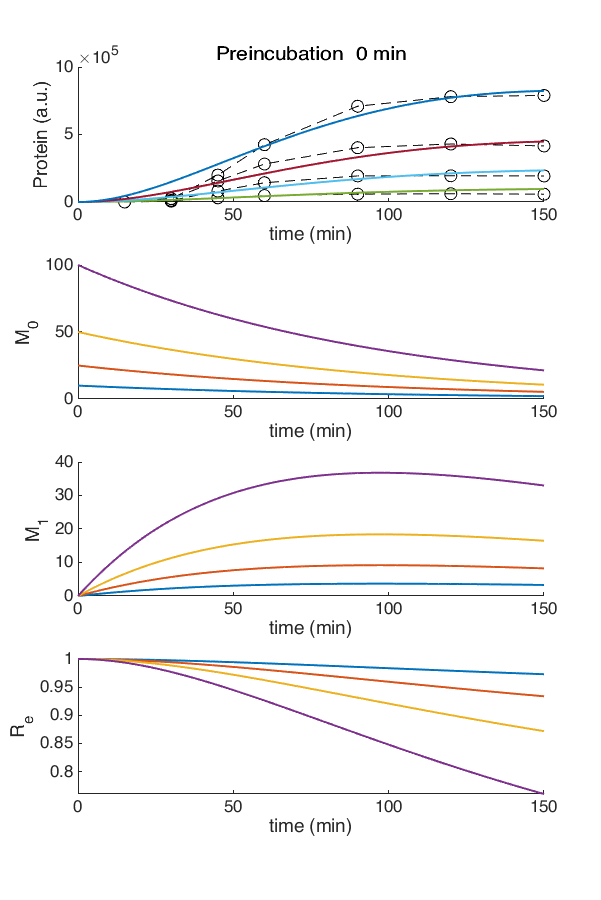

Final Parameter Values:
    "a_P"    "a_R"    "d_P"    "betta"    "gamma"

       458.55   6.1815e-05      0.01339   4.2876e-05      0.01029

Final Error:
   2.3036e+05



%%%%%%%%% Model Fit %%%%%%%%%
params = IVT_model_fit_complete(scale_limits, ...
    time_points, ...
    protein_level, ...
    concentrations, ...
    preincubation_times, ...
    n, param_selection, ...
    Nb_step, neld_param, TIME, deltat, ...
    file_name, loss_scale);

%%%%%%%%% Model Plotting %%%%%%%%%
% close;
% param_setting = [1e4 1e-3 1e-3 1e-3 1e-5 1e-3];
% disp(param_setting);
% IVT_model_fit_plot(scale_limits, time_points, protein_level, concentrations, ...
%   preincubation_times, n, param_selection, TIME, deltat, param_setting)
%%%%%%%%%%%%%%% Steady State %%%%%%%%%
%alpha_p = params(1);
% alpha_m = params(2);
% alpha_e = params(3);
% delta_p = params(4);
% delta_m = params(5);
% delta_e = params(6);
% r_p = params(7);
% betta = (r_p/delta_e - (alpha_e*delta_p)/(delta_e*alpha_p)*(-alpha_m*delta_p/(delta_m*alpha_p)));
% P_ss = delta_p/(betta*alpha_p);
% M_ss = (-alpha_m/(betta*delta_m))*(delta_p/alpha_p)^2;
% R_ss = ((r_p*delta_p/(betta*delta_e*alpha_p)) - (alpha_e/(betta*delta_e))*(delta_p/alpha_p)^2);